close("all"); clear; clc;

x = OptimizationVariables(sym('t'),2,1);
x.ParameterLowerBound = 0;
x.ControlLowerBounds = -1;
x.ControlUpperBounds = 1;

plant = Plant(x,@slidingMass,1);

J = Cost(x,@(x,u)1 + 0.*u(1,:));

ocp = OptimalControlProblem(x,J,plant);
ocp.InitialTime = 0;
ocp.InitialState = [0;0];
ocp.FinalState = [1;0];
disp(ocp)

MINIMIZE:


$$\int_{0}^{t_{f}}1\mathrm{d}t$$

SUBJECT TO:

Dynamic constraints:


$$\left[\begin{array}{c} \frac{\partial }{\partial t}x_{1}\left(t\right)=x_{2}\left(t\right)\\ \frac{\partial }{\partial t}x_{2}\left(t\right)=u_{1}\left(t\right) \end{array}\right]$$

Parameter bounds:


$$1<t_{f}$$

Control bounds:


$$\left(-1\leq u_{1}\left(t\right)\right)\leq 1$$

N = 10;
cc = DirectCollocation(@trapezoidalDefect,ocp,N);
x10 = linspace(ocp.InitialState(1),ocp.FinalState(1),N);
x20 = linspace(ocp.InitialState(2),ocp.FinalState(2),N);
x0 = [x10;x20];
u0 = linspace(1,-1,N);
cc.initialGuess(x0,u0);

opts = optimoptions("fmincon", ...
    "MaxFunctionEvaluations",1E05 ...
    );
[t0,tf,x,u] = cc.optimize(opts);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


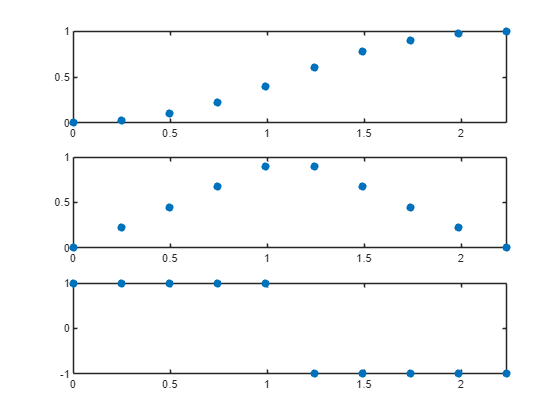

results = [x;u];
tiledlayout(3,1);
for i = 1:size(results,1)
    nexttile;
    scatter(linspace(t0,tf,N),results(i,:),"filled");
    xlim([0,tf]);
    box("on");
end